# CNN para classificacao de batimentos **ectópicos** (divisao intra-paciente)

Base: MITBIH_Beats.mat

Estrutura esperada da base:

beats    -> 181 x N

labels   -> 1 x N

patientId -> 1 x N

clear; clc;

## 1) Carrega a base

basePath = 'D:\ProcessamentoDeSinais\TCC\Model\extBati\MITBIH_Beats.mat';
load(basePath);

beats = double(beats);
labels = double(labels(:).');
patientId = double(patientId(:).');

if size(beats, 2) ~= numel(labels)
    beats = beats.';
end

## 2) Divisao intra-paciente



patientList = unique(patientId);
idxTrain = [];
idxVal   = [];
idxTest  = [];

rng(42);

for i = 1:numel(patientList)
    pid = patientList(i);
    idxPaciente = find(patientId == pid);
    labelsPaciente = labels(idxPaciente);

    % Embaralha os indices do paciente
    idxPaciente = idxPaciente(randperm(numel(idxPaciente)));

    % Proporcao 70/15/15 dentro do paciente
    n = numel(idxPaciente);
    nTrain = floor(0.70 * n);
    nVal   = floor(0.15 * n);
    nTest  = n - nTrain - nVal;

    % Ajusta para garantir que exista ao menos 1 amostra em cada conjunto
    if nTrain == 0, nTrain = 1; end
    if nVal == 0 && n > 1, nVal = 1; end
    if nTest == 0 && n > 1, nTest = 1; end

    % Recalcula para garantir que a soma nao exceda o total do paciente
    totalAjustado = nTrain + nVal + nTest;
    while totalAjustado > n
        if nTest > 0
            nTest = nTest - 1;
        elseif nVal > 0
            nVal = nVal - 1;
        else
            nTrain = nTrain - 1;
        end
        totalAjustado = nTrain + nVal + nTest;
    end

    % Se ainda ficou zero em algum conjunto, corrige
    if nTrain == 0 && n > 1, nTrain = 1; end
    if nVal == 0 && n > 2, nVal = 1; end
    if nTest == 0 && n > 3, nTest = 1; end

    % Reajuste final para evitar excesso
    while nTrain + nVal + nTest > n
        if nTest > 0
            nTest = nTest - 1;
        elseif nVal > 0
            nVal = nVal - 1;
        else
            nTrain = nTrain - 1;
        end
    end

    % Garante que o total do paciente continue sendo usado
    if nTrain + nVal + nTest < n
        restante = n - (nTrain + nVal + nTest);
        nTest = nTest + restante;
    end

    % Distribuicao final
    trainIdx = idxPaciente(1:nTrain);
    valIdx   = idxPaciente(nTrain+1:nTrain+nVal);
    testIdx  = idxPaciente(nTrain+nVal+1:end);

    % Caso o ultimo conjunto fique vazio por algum paciente pequeno
    if isempty(testIdx) && numel(idxPaciente) > 1
        testIdx = idxPaciente(end);
        valIdx = setdiff(valIdx, testIdx);
    end

    idxTrain = [idxTrain, trainIdx];
    idxVal   = [idxVal, valIdx];
    idxTest  = [idxTest, testIdx];
end

% Remove possiveis indices duplicados ou vazios
idxTrain = unique(idxTrain(:));
idxVal   = unique(idxVal(:));
idxTest  = unique(idxTest(:));

% Garante separacao correta
if isempty(idxTrain) || isempty(idxVal) || isempty(idxTest)
    error('A divisao intra-paciente gerou algum subconjunto vazio. Verifique a quantidade de amostras por paciente.');
end


## **3) Monta os tensores de entrada**

Xtrain = reshape(beats(:, idxTrain), [181, 1, 1, numel(idxTrain)]);
Xval   = reshape(beats(:, idxVal),   [181, 1, 1, numel(idxVal)]);
Xtest  = reshape(beats(:, idxTest),  [181, 1, 1, numel(idxTest)]);

Ytrain = categorical(labels(idxTrain), [0 1], {'Normal', 'Ectopic'});
Yval   = categorical(labels(idxVal),   [0 1], {'Normal', 'Ectopic'});
Ytest  = categorical(labels(idxTest),  [0 1], {'Normal', 'Ectopic'});
classNames = categories(Ytrain);


## 4) Arquitetura CNN 1D

Quatro convolucoes acopladas (C1-C2 e C3-C4), dois max-poolings

 (S1 e S2), dropout apos C2, C4, F1 e F2, e tres camadas densas

(a ultima foi ajustada para as duas classes desta base).

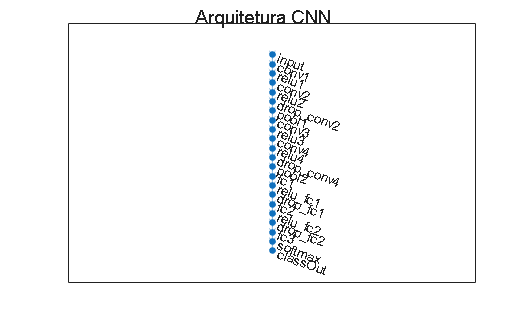

layers = [
    imageInputLayer([181 1 1], 'Name', 'input', 'Normalization', 'none')

    convolution2dLayer([5 1], 32, 'Padding', 'same', 'Name', 'conv1')
    reluLayer('Name', 'relu1')

    convolution2dLayer([5 1], 32, 'Padding', 'same', 'Name', 'conv2')
    reluLayer('Name', 'relu2')
    dropoutLayer(0.5, 'Name', 'drop_conv2')
    maxPooling2dLayer([2 1], 'Stride', [2 1], 'Name', 'pool1')

    convolution2dLayer([3 1], 64, 'Padding', 'same', 'Name', 'conv3')
    reluLayer('Name', 'relu3')

    convolution2dLayer([3 1], 128, 'Padding', 'same', 'Name', 'conv4')
    reluLayer('Name', 'relu4')
    dropoutLayer(0.5, 'Name', 'drop_conv4')
    maxPooling2dLayer([2 1], 'Stride', [2 1], 'Name', 'pool2')

    fullyConnectedLayer(128, 'Name', 'fc1')
    reluLayer('Name', 'relu_fc1')
    dropoutLayer(0.5, 'Name', 'drop_fc1')
    fullyConnectedLayer(64, 'Name', 'fc2')
    reluLayer('Name', 'relu_fc2')
    dropoutLayer(0.5, 'Name', 'drop_fc2')
    fullyConnectedLayer(2, 'Name', 'fc3')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classOut', 'Classes', classNames)
];

deepNetworkDesigner(layers);

lgraph = layerGraph(layers);

figure;
plot(lgraph) 
sgtitle('Arquitetura CNN');

## 5) Opções de treinamento

options = trainingOptions('adam', ...
    'InitialLearnRate', 1e-3, ...
    'MaxEpochs', 50, ...
    'MiniBatchSize', 256, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {Xval, Yval}, ...
    'ValidationFrequency', 30, ...
    'ValidationPatience', 10, ...
    'Verbose', true, ...
    'Plots', 'training-progress');


## 6) Treinamento

 Fixa a inicializacao da rede para comparacoes reproduziveis.

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:10 |       61.72% |       80.67% |       0.6792 |       0.5927 |          0.0010 |
|       1 |          30 |       00:00:25 |       86.72% |       88.64% |       0.3734 |       0.3240 |          0.0010 |
|       1 |          50 |       00:00:33 |       87.89% |              |       0.3925 |              |          0.0010 |
|       1 |          60 |       00:00:40 |       91.41% |       91.67% |       0.3025 |       0.3154 |          0.0010 |
|       

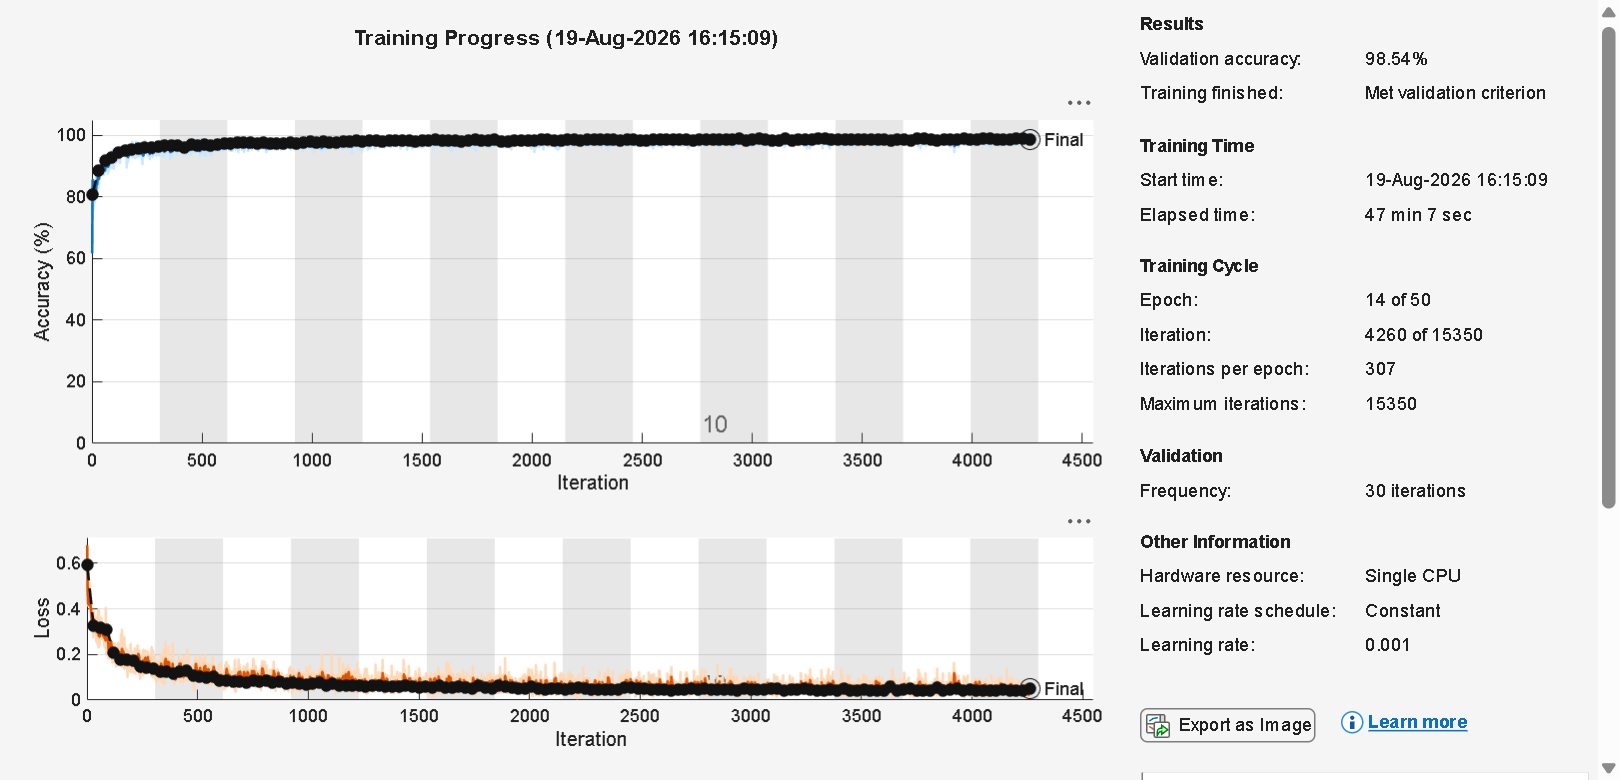

rng(42);
net = trainNetwork(Xtrain, Ytrain, layers, options);

## 7) Avaliação

% Seleciona o limiar da classe Ectopic exclusivamente na validacao,
% maximizando o F1-score. Em caso de empate, usa o valor mais proximo de 0.5.
[~, scoresVal] = classify(net, Xval);
ectopicIdx = find(strcmp(classNames, 'Ectopic'), 1);
thresholds = (0:0.01:1).';
f1Val = zeros(numel(thresholds), 1);
isEctopicVal = Yval(:) == 'Ectopic';

for i = 1:numel(thresholds)
    predEctopicVal = scoresVal(:, ectopicIdx) >= thresholds(i);
    tp = sum(predEctopicVal & isEctopicVal);
    fp = sum(predEctopicVal & ~isEctopicVal);
    fn = sum(~predEctopicVal & isEctopicVal);

    if (2 * tp + fp + fn) > 0
        f1Val(i) = (2 * tp) / (2 * tp + fp + fn);
    end
end

bestF1Val = max(f1Val);
candidateIdx = find(abs(f1Val - bestF1Val) < eps);
[~, nearestToHalf] = min(abs(thresholds(candidateIdx) - 0.5));
bestIdx = candidateIdx(nearestToHalf);
optimalThreshold = thresholds(bestIdx);

% Aplica no teste somente o limiar definido acima.
[~, scoresTest] = classify(net, Xtest);
YPred = categorical(repmat({'Normal'}, numel(Ytest), 1), classNames);
YPred(scoresTest(:, ectopicIdx) >= optimalThreshold) = 'Ectopic';

% Acuracia global
acc = mean(YPred(:) == Ytest(:));

% Classes existentes
classes = categories(Ytest);
numClasses = numel(classes);

% Matriz de confusao
cm = confusionmat(Ytest, YPred, ...
    'Order', categorical(classes));

fprintf('\n============================================\n');

fprintf('        AVALIACAO NO CONJUNTO DE TESTE\n');

        AVALIACAO NO CONJUNTO DE TESTE


fprintf('============================================\n');


fprintf('Acuracia: %.4f (%.2f%%)\n', acc, acc*100);

Acuracia: 0.9844 (98.44%)


fprintf('Limiar otimo para Ectopic na validacao: %.2f (F1 = %.4f)\n', ...
    optimalThreshold, bestF1Val);

Limiar otimo para Ectopic na validacao: 0.56 (F1 = 0.9632)



%% Calculo das metricas por classe

precision   = zeros(numClasses,1);
sensitivity = zeros(numClasses,1);
specificity = zeros(numClasses,1);
f1score     = zeros(numClasses,1);

totalSamples = sum(cm(:));

for i = 1:numClasses

    % Verdadeiros positivos
    TP = cm(i,i);

    % Falsos positivos
    FP = sum(cm(:,i)) - TP;

    % Falsos negativos
    FN = sum(cm(i,:)) - TP;

    % Verdadeiros negativos
    TN = totalSamples - TP - FP - FN;

    % Precisao / PPV
    if (TP + FP) > 0
        precision(i) = TP / (TP + FP);
    else
        precision(i) = 0;
    end

    % Sensibilidade / Recall
    if (TP + FN) > 0
        sensitivity(i) = TP / (TP + FN);
    else
        sensitivity(i) = 0;
    end

    % Especificidade
    if (TN + FP) > 0
        specificity(i) = TN / (TN + FP);
    else
        specificity(i) = 0;
    end

    % F1-score
    if (precision(i) + sensitivity(i)) > 0
        f1score(i) = 2 * ...
            (precision(i) * sensitivity(i)) / ...
            (precision(i) + sensitivity(i));
    else
        f1score(i) = 0;
    end
end

%% Tabela de resultados por classe

metricas = table( ...
    categorical(classes), ...
    precision, ...
    sensitivity, ...
    specificity, ...
    f1score, ...
    'VariableNames', { ...
    'Classe', ...
    'Precisao', ...
    'Sensibilidade', ...
    'Especificidade', ...
    'F1_Score'});

disp(' ');

disp('Metricas por classe:');

Metricas por classe:


disp(metricas);

    Classe     Precisao    Sensibilidade    Especificidade    F1_Score
    _______    ________    _____________    ______________    ________

    Normal     0.98569        0.99499           0.9417        0.99032 
    Ectopic    0.97897         0.9417          0.99499        0.95998 




%% Metricas macro

precisionMacro   = mean(precision);
sensitivityMacro = mean(sensitivity);
specificityMacro = mean(specificity);
f1Macro          = mean(f1score);

fprintf('\n--------------------------------------------\n');


--------------------------------------------


fprintf('Metricas macro:\n');

Metricas macro:


fprintf('Precisao macro:       %.4f (%.2f%%)\n', ...
    precisionMacro, precisionMacro*100);

Precisao macro:       0.9823 (98.23%)



fprintf('Sensibilidade macro:  %.4f (%.2f%%)\n', ...
    sensitivityMacro, sensitivityMacro*100);

Sensibilidade macro:  0.9683 (96.83%)



fprintf('Especificidade macro: %.4f (%.2f%%)\n', ...
    specificityMacro, specificityMacro*100);

Especificidade macro: 0.9683 (96.83%)



fprintf('F1-score macro:       %.4f (%.2f%%)\n', ...
    f1Macro, f1Macro*100);

F1-score macro:       0.9751 (97.51%)



fprintf('--------------------------------------------\n');

--------------------------------------------


## Matriz de confusão

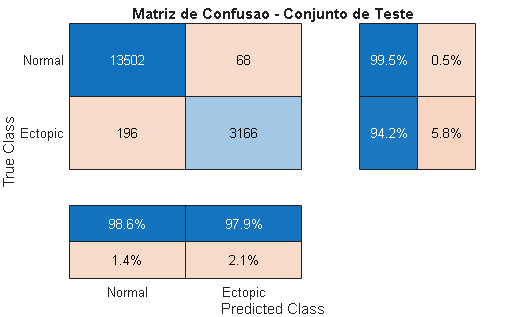


figure;

confusionchart(Ytest, YPred, ...
    'RowSummary', 'row-normalized', ...
    'ColumnSummary', 'column-normalized');

title('Matriz de Confusao - Conjunto de Teste');

### 8) Matriz de confusão normalizada

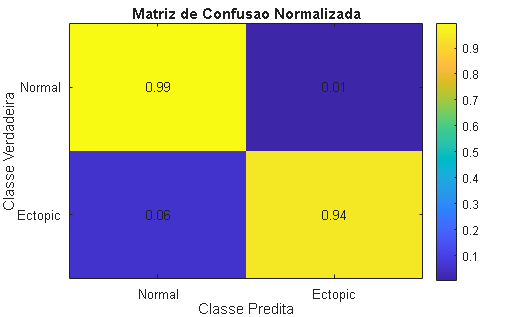


cmNormalized = cm ./ sum(cm, 2);

% Evita NaN caso alguma classe nao possua amostras
cmNormalized(isnan(cmNormalized)) = 0;

figure;

imagesc(cmNormalized);
colorbar;

title('Matriz de Confusao Normalizada');
xlabel('Classe Predita');
ylabel('Classe Verdadeira');

xticks(1:numClasses);
yticks(1:numClasses);

xticklabels(classes);
yticklabels(classes);

% Mostrar os valores dentro da matriz
for i = 1:numClasses
    for j = 1:numClasses
        text(j, i, sprintf('%.2f', cmNormalized(i,j)), ...
            'HorizontalAlignment', 'center', ...
            'VerticalAlignment', 'middle');
    end
end

### Identificação da pior classe


[~, idxWorst] = min(f1score);

fprintf('\nClasse com menor F1-score: %s\n', ...
    string(classes(idxWorst)));


Classe com menor F1-score: Ectopic



fprintf('F1-score da classe: %.4f\n', ...
    f1score(idxWorst));

F1-score da classe: 0.9600



fprintf('Sensibilidade: %.4f\n', ...
    sensitivity(idxWorst));

Sensibilidade: 0.9417



fprintf('Precisao: %.4f\n', ...
    precision(idxWorst));

Precisao: 0.9790


## Visualizacao de algumas predições

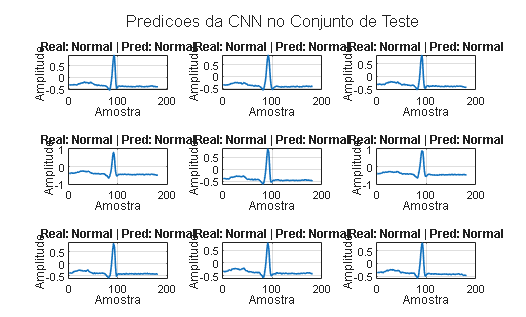


numSamplesPlot = min(9, numel(Ytest));

figure;

tiledlayout(3,3);

for i = 1:numSamplesPlot

    nexttile;

    % Extrai a primeira amostra
    signal = squeeze(Xtest(:,1,1,i));

    plot(signal, 'LineWidth', 1.2);
    grid on;

    title(sprintf( ...
        'Real: %s | Pred: %s', ...
        string(Ytest(i)), ...
        string(YPred(i))));

    xlabel('Amostra');
    ylabel('Amplitude');

end

sgtitle('Predicoes da CNN no Conjunto de Teste');

##  Resultado da primeira amostra


fprintf('\n============================================\n');

fprintf('Primeira amostra do conjunto de teste:\n');

Primeira amostra do conjunto de teste:


fprintf('Classe verdadeira: %s\n', string(Ytest(1)));

Classe verdadeira: Normal


fprintf('Classe prevista:   %s\n', string(YPred(1)));

Classe prevista:   Normal


fprintf('============================================\n');